# Set data

N = 257; % x,y sampling points
lambda = 633; % wavelength in nm
k = 2*pi/lambda;
m = 100;
z = m*lambda; % propargate distance
z = reshape(repmat(z,256*256,1),256,256,[]);
Endpoint = 0.012*lambda; % size/2
w = 0.7E-3*lambda; % rect width


## Create field at starting point (z=0)

x = linspace(-Endpoint,Endpoint,N); 
x = x(1:end-1); 
dx = x(2)-x(1);
xi = linspace(-dx/2,dx/2,N); 
xi = xi(1:end-1); 

y = linspace(-Endpoint,Endpoint,N);
y = y(1:end-1);
dy = y(2)-y(1);
eta = linspace(-dy/2,dy/2,N);
eta = eta(1:end-1);

[X,Y] = meshgrid(x,y);
[Xi,Eta] = meshgrid(xi,eta);

% rect function as an object
ur_o=(X>-w&X<w)&(Y>-w&Y<w);

## Fourier Transform of object (ur_o)

% Fourier transformed rect function
ur_o = fftshift(ur_o);
Ur_o = fft2(ur_o);
Ur_o = ifftshift(Ur_o); 

## Calculate propagation in Fourier space

% Uph = exp(2*pi*z*sqrt(lambda^-2-(xi^2+eta^2))
% f(x)=1 for x>-0.5 & x<0.5
Uph = exp(2*pi*1i*sqrt((lambda^-2)-(Xi.^2+Eta.^2)).*z);
U=Ur_o.*Uph;

## Inverse Fourier Transform of U

U = fftshift(U);
u = ifft2(U);
u = ifftshift(u); 

## Parabolic approximation

H = exp(1i*k.*z).*exp(-1i*pi*lambda .*z.*(Xi.^2+ Eta .^2));
U_p = Ur_o.*H;

## Inverse Fourier Transform of U_p (parabolic approx.)

U_p = fftshift(U_p);
u_p = ifft2(U_p);
u_p = ifftshift(u_p);

## Results

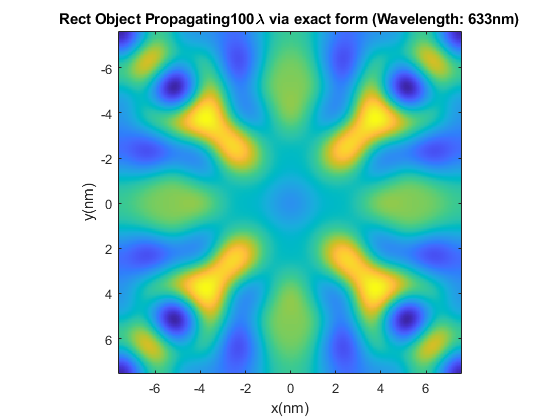

imagesc(x,y,real(u))
axis square
title(['Rect Object Propagating' num2str(m) '\lambda via exact form (Wavelength: ' num2str(lambda) 'nm)'])
xlabel('x(nm)')
ylabel('y(nm)')
saveas(gcf,"Q4_figure/HW4_Q4_"+num2str(m)+"lambda_exact_form",'jpg') 

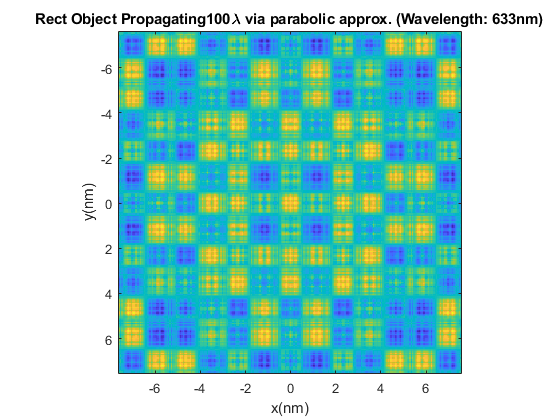


imagesc(x,y,real(u_p))
axis square
title(['Rect Object Propagating' num2str(m) '\lambda via parabolic approx. (Wavelength: ' num2str(lambda) 'nm)'])
xlabel('x(nm)')
ylabel('y(nm)')
saveas(gcf,"Q4_figure/HW4_Q4_"+num2str(m)+"lambda_parabolic_approximation",'jpg') 